# Basis Details(Quantum Mechanics with MATLAB)

## Abstract

## Introduction

## 1 S=1/2

### 1.1. Define a spin

**We set **$\hbar =1$

spin up

spin_up = Spin(1/2,1/2)

spin_up = |1/2,1/2⟩

spin dn

spin_dn = Spin(1/2,-1/2)

spin_dn = |1/2,-1/2⟩

a pair of spin 

spin_basis = Spin(1/2)

spin_basis = |1/2,1/2⟩ 
|1/2,-1/2⟩ 

[1/2,-1/2] together

spin_basis_x = Spin(1/2,[1/2,-1/2],[1 1])

spin_basis_x = |1/2,1/2⟩ + |1/2,-1/2⟩ 

spin_basis_y = Spin(1/2,[1/2,-1/2],[1 -1])% why?

spin_basis_y = |1/2,1/2⟩ + -|1/2,-1/2⟩ 

### 1.2. Pauli matrices


$$\hat{\mathbf{S}}=\frac{\hbar}{2} \sigma$$


Sxm = spin_basis.Sx

$$Sxm = \left(\begin{array}{cc} 0 & \frac{1}{2}\\ \frac{1}{2} & 0 \end{array}\right)$$

Sym = spin_basis.Sy

$$Sym = \left(\begin{array}{cc} 0 & -\frac{1}{2}\,\mathrm{i}\\ \frac{1}{2}\,\mathrm{i} & 0 \end{array}\right)$$

Szm = spin_basis.Sz

$$Szm = \left(\begin{array}{cc} \frac{1}{2} & 0\\ 0 & -\frac{1}{2} \end{array}\right)$$

spin_basis_y.Sx

$$ans = -1$$

spin_basis_y.Sy % why?

$$ans = 0$$

### 1.3. Permutation

spin_basis_x

spin_basis_x = |1/2,1/2⟩ + |1/2,-1/2⟩ 

spin_basis_x.Prow([2,1])

ans = -|1/2,-1/2⟩ + -|1/2,1/2⟩ 

### 1.4. **Rotations(right)**

For a rotation by angle *θ* in the plane with normal vector $\hat{\theta}$

 we use  $U=e^{\;\frac{i}{\hbar \;}\theta \cdot S}$

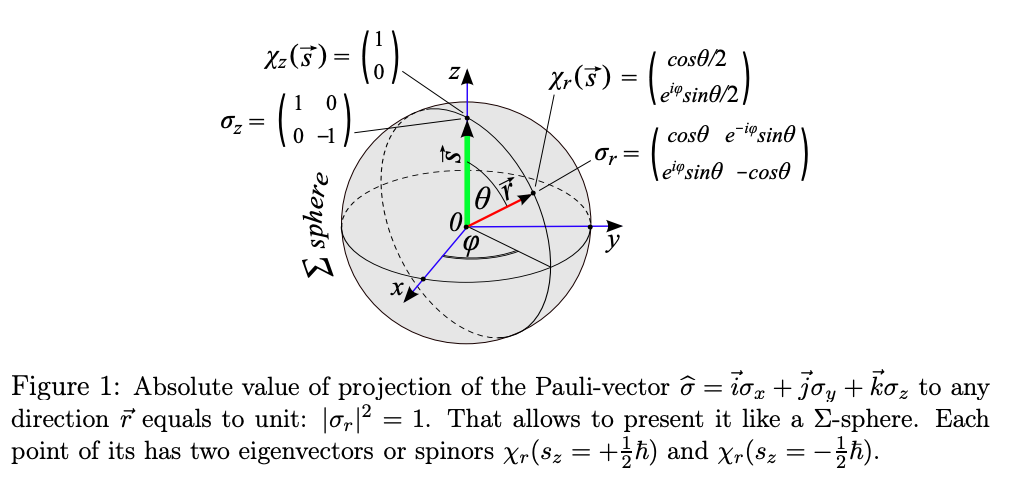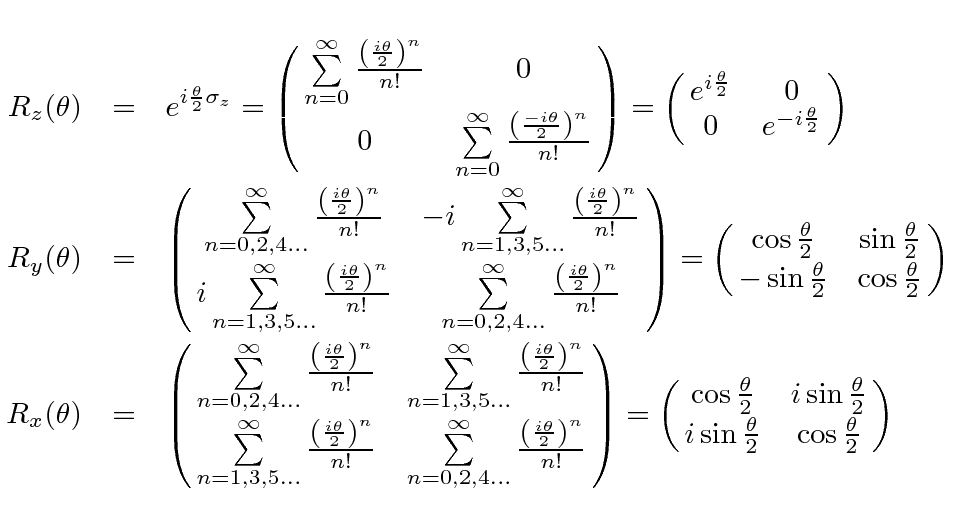

syms theta real;
assume(theta<pi/2);
assume(theta>0);
Rz_theta= simplify(rewrite(spin_basis.rotation([0 0 1 theta]),'exp'),'IgnoreAnalyticConstraints',true)

Immproper input: Euler angle ZYZ format expected [alpha beta gamma]


$$Rz\_theta = \left(\begin{array}{cc} {\mathrm{e}}^{\frac{\theta \,\mathrm{i}}{2}} & 0\\ 0 & {\mathrm{e}}^{-\frac{\theta \,\mathrm{i}}{2}} \end{array}\right)$$

theta = sym(pi/3);
Ry_theta= simplify(rewrite(spin_basis.rotation([0 1 0 theta]),'exp'),'IgnoreAnalyticConstraints',true)

Immproper input: Euler angle ZYZ format expected [alpha beta gamma]


$$Ry\_theta = \left(\begin{array}{cc} \frac{\sqrt{3}}{2} & \frac{1}{2}\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} \end{array}\right)$$

Rx_theta= simplify(rewrite(spin_basis.rotation([1 0 0 theta]),'exp'),'IgnoreAnalyticConstraints',true)

Immproper input: Euler angle ZYZ format expected [alpha beta gamma]


$$Rx\_theta = \left(\begin{array}{cc} \frac{\sqrt{3}}{2} & \frac{1}{2}\,\mathrm{i}\\ \frac{1}{2}\,\mathrm{i} & \frac{\sqrt{3}}{2} \end{array}\right)$$

syms theta real;
M_theta = simplify(rewrite(spin_basis.rotation([cos(theta) sin(theta)  0 pi]),'exp'),'IgnoreAnalyticConstraints',true)

Immproper input: Euler angle ZYZ format expected [alpha beta gamma]


$$M\_theta = \left(\begin{array}{cc} 0 & -{\mathrm{e}}^{-\theta \,\mathrm{i}}\,\mathrm{i}\\ -{\mathrm{e}}^{\theta \,\mathrm{i}}\,\mathrm{i} & 0 \end{array}\right)$$

spin_basis

spin_basis = |1/2,1/2⟩ 
|1/2,-1/2⟩ 

spin_basis.rotate([cos(theta) sin(theta)  0 pi])

ans = (- cos(2*theta) - sin(2*theta)*1i)^(1/2)/abs(cos(2*theta) + sin(2*theta)*1i)^(1/2)|1/2,-1/2⟩ 
-abs(cos(2*theta) + sin(2*theta)*1i)^(1/2)/(- cos(2*theta) - sin(2*theta)*1i)^(1/2)|1/2,1/2⟩ 

### 1.5. Measurement of spin along the x, y, or z axes

Vup = spin_up.EigenVectors;
Vdn = spin_dn.EigenVectors;

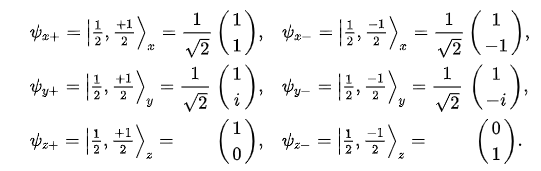

phi_x_plus = Vup{1} 

$$phi\_x\_plus = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

phi_y_plus = Vup{2}*1i

$$phi\_y\_plus = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}\,\mathrm{i}}{2} \end{array}\right)$$

phi_z_plus = Vup{3} 

$$phi\_z\_plus = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

phi_x_minus = Vdn{1} *-1

$$phi\_x\_minus = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ -\frac{\sqrt{2}}{2} \end{array}\right)$$

phi_y_minus = Vdn{2} *-1i

$$phi\_y\_minus = \left(\begin{array}{c} \frac{\sqrt{2}}{2}\\ -\frac{\sqrt{2}\,\mathrm{i}}{2} \end{array}\right)$$

phi_z_minus = Vdn{3} 

$$phi\_z\_minus = \left(\begin{array}{c} 0\\ 1 \end{array}\right)$$

### 1.6. Parity

spin_basis.parity

ans = 1

ans = 1

## 2. Spin-1(Triplet state)

### 2.1. Define a lm basis

lm(1)

ans = |1,1⟩ + |1,0⟩ + |1,-1⟩ 

### 2.2. CG 


$$\left|j_{1} j_{2} ; j m\right\rangle=\sum_{m_{1}+m_{2}=m}\left|j_{1} j_{2} ; m_{1} m_{2}\right\rangle\left\langle j_{1} j_{2} ; m_{1} m_{2} \mid j_{1} j_{2} ; j m\right\rangle =\sum_{m_{1}+m_{2}=m} C_{m_{1} m_{2}}^{j}\left|j_{1} j_{2} ; m_{1} m_{2}\right\rangle
$$


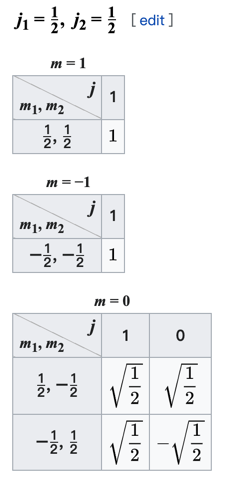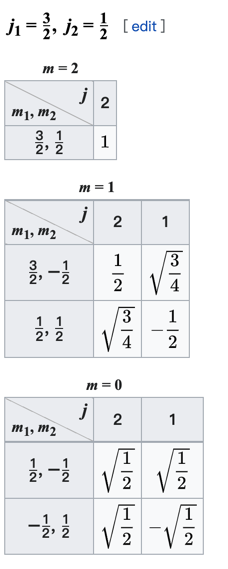

CGsingle(1/2,1/2,0,-1/2,1/2,0)

$$ans = -\frac{\sqrt{2}}{2}$$

CGsingle(3/2,1/2,1,3/2,-1/2,1)

$$ans = \frac{\sqrt{3}}{2}$$

### 2.3. Two spin-1/2 particles

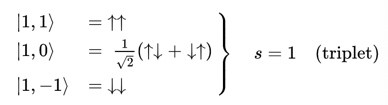

NewSpin = spin_basis*spin_basis

NewSpin = |1,1⟩ + 
0.707|0,0⟩ + 0.707|1,0⟩ 
-0.707|0,0⟩ + 0.707|1,0⟩ 
|1,-1⟩ + 

how to define contract problem !!

NewSpin_2 = NewSpin.Pmat([1 0 0 0;0 1/sqrt(2) 1/sqrt(2) 0;0 0 0 1;0 1/sqrt(2) -1/sqrt(2) 0])

NewSpin_2 = |1,1⟩ 
|1,0⟩ 
|1,-1⟩ 
|0,0⟩ 

### 2.4. Singlet

U(1)

Singlet = NewSpin_2(4)

Singlet = |0,0⟩

### 2.5. Triplet

SO(3)

Triplet = NewSpin_2([3,2,1])

Triplet = |1,-1⟩ 
|1,0⟩ 
|1,1⟩ 

Triplet = lm(Triplet)

Triplet = |1,-1⟩ 
|1,0⟩ 
|1,1⟩ 

#### 2.5.1. rotation for Triplet(3D rotation group)

$J_x =\frac{\sqrt{2}}{2}\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
1 & 0 & 1\\
0 & 1 & 0
\end{array}\right\rbrack$,$J_y =\frac{\sqrt{2}}{2}\left\lbrack \begin{array}{ccc}
0 & -i & 0\\
i & 0 & -i\\
0 & i & 0
\end{array}\right\rbrack$,$J_z =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 0 & 0\\
0 & 0 & -1
\end{array}\right\rbrack$

Specifically, ${\textrm{UJ}}_i {\mathrm{U}}^{\dagger\;} ={\textrm{iL}}_i$ $U=\frac{1}{\sqrt{2}}\left\lbrack \begin{array}{ccc}
-1 & 0 & 1\\
-i & 0 & -i\\
0 & \sqrt{2} & 0
\end{array}\right\rbrack$

$L_x =\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & -1\\
0 & 1 & 0
\end{array}\right\rbrack$,$L_y =\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 0 & 0\\
- & 0 & 0
\end{array}\right\rbrack$,$L_z =\left\lbrack \begin{array}{ccc}
0 & -1 & 0\\
1 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$

J_x = Triplet.JX

$$J\_x = \left(\begin{array}{ccc} 0 & \frac{\sqrt{2}}{2} & 0\\ \frac{\sqrt{2}}{2} & 0 & \frac{\sqrt{2}}{2}\\ 0 & \frac{\sqrt{2}}{2} & 0 \end{array}\right)$$

J_y = Triplet.JY

$$J\_y = \left(\begin{array}{ccc} 0 & -\frac{\sqrt{2}\,\mathrm{i}}{2} & 0\\ \frac{\sqrt{2}\,\mathrm{i}}{2} & 0 & -\frac{\sqrt{2}\,\mathrm{i}}{2}\\ 0 & \frac{\sqrt{2}\,\mathrm{i}}{2} & 0 \end{array}\right)$$

J_z = Triplet.JZ

$$J\_z = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & -1 \end{array}\right)$$

L_x = Triplet.Lx

$$L\_x = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & -1\\ 0 & 1 & 0 \end{array}\right)$$

L_y = Triplet.Ly

$$L\_y = \left(\begin{array}{ccc} 0 & 0 & 1\\ 0 & 0 & 0\\ -1 & 0 & 0 \end{array}\right)$$

L_z = Triplet.Lz

$$L\_z = \left(\begin{array}{ccc} 0 & -1 & 0\\ 1 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


$$\hat{R}({\bf{\theta}}) \equiv \exp \left(\theta_{i} \hat{L}_{i}\right)$$



$$R_z \left(\theta \right)=\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & -\sin \left(\theta \right) & 0\\
\sin \left(\theta \right) & \cos \left(\theta \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$

$$R_x \left(\theta \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(\theta \right) & -\sin \left(\theta \right)\\
0 & \sin \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack$$

$$R_y \left(\theta \right)=\left\lbrack \begin{array}{ccc}
\cos \left(\theta \right) & 0 & \sin \left(\theta \right)\\
0 & 1 & 0\\
-\sin \left(\theta \right) & 0 & \cos \left(\theta \right)
\end{array}\right\rbrack$$


syms theta real
R_z = expm(theta*L_z)

$$R\_z = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R_x = expm(theta*L_x)

$$R\_x = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

R_y = expm(theta*L_y)

$$R\_y = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

## 3. Basis function

Basis function is designed for a Basis with three component :

orbital position (fractional coordinate)[ ] , Orbital function( Symbolic Expression with x y z) , Spin function

Use row vector as a liner combination

Use col vector for different Bais function

### 3.1. From Spin

A Basis function can be [ AtomicOrbital;Ylm(Spherical Harmonics); BasisFunctionFromIR(Group Theory);SymSymble;PlaneWave(waiting...) ]

BasisFunctionSpin = BasisFunc(Spin(1/2))

BasisFunctionSpin = 2×1 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionSpin(1).spin

ans = |1/2,1/2⟩

BasisFunctionSpin(2).spin

ans = |1/2,-1/2⟩

BasisFunctionBHZ = BasisFunc([...
    Spin(1/2,1/2,'parity',1),...
    Spin(3/2,3/2,'parity',-1),...
    Spin(1/2,-1/2,'parity',1),...
    Spin(3/2,-3/2,'parity',-1)])

BasisFunctionBHZ = 1×4 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionBHZ.dispAll();

11|1/2,1/2⟩  + 11|3/2,3/2⟩  + 11|1/2,-1/2⟩  + 11|3/2,-3/2⟩ 


BasisFunctionBHZ = BasisFunc([...
    Spin(1/2,1/2,'parity',1);...
    Spin(3/2,3/2,'parity',-1);...
    Spin(1/2,-1/2,'parity',1);...
    Spin(3/2,-3/2,'parity',-1)])

BasisFunctionBHZ = 4×1 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionBHZ.dispAll();

11|1/2,1/2⟩ 
11|3/2,3/2⟩ 
11|1/2,-1/2⟩ 
11|3/2,-3/2⟩ 


### 3.2. From ${\mathbf{Y}}_{\mathbf{l}}^{\mathbf{m}}$or${\mathbf{Y}}_{\textrm{lm}}$(Atomic orbital)

BasisFunctionSpin = BasisFunc(Y_l__m(1))

BasisFunctionSpin = 3×1 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionSpin.dispAll()

1-(2^(1/2)*(p_x + p_y*1i))/2|0,0⟩ 
1p_z|0,0⟩ 
1(2^(1/2)*(p_x - p_y*1i))/2|0,0⟩ 


BasisFunctionP = BasisFunc({Y_lm(1,0);Y_lm(1,1);Y_lm(1,-1)})

BasisFunctionP = 3×1 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionP2 = BasisFunc([Y_lm(1,0);Y_lm(1,1);Y_lm(1,-1)])

BasisFunctionP2 = 3×2 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionP.dispAll()

1p_z|0,0⟩ 
1p_x|0,0⟩ 
1p_y|0,0⟩ 


BasisFunctionP2.dispAll()

1p_z/2|0,0⟩  + 1p_z/2|0,0⟩ 
1p_x/2 - (p_y*1i)/2|0,0⟩  + 1p_x/2 + (p_y*1i)/2|0,0⟩ 
1(p_x*1i)/2 + p_y/2|0,0⟩  + 1p_y/2 - (p_x*1i)/2|0,0⟩ 


celldisp(BasisFunctionP(2).BFuncL)

 
ans{1} =
 


$$p_{x}$$

### 3.3. From symbolic expression with var(x,y,z)

syms x y z real;
BasisFunctionC5 = BasisFunc({x*y*z*(x^2-y^2);y*z;z*x})

BasisFunctionC5 = 3×1 BasisFunc array with properties:
    BForb
    BFnum
    BFuncL
    spin
    coe


BasisFunctionC5.dispAll()

1x*y*z*(x^2 - y^2)|0,0⟩ 
1y*z|0,0⟩ 
1x*z|0,0⟩ 


### 3.4. From quantumL

TBkittmp1 = TBkit;
TBkittmp2 = TBkit;
TBkittmp1 = TBkittmp1.input_orb_struct('POSCAR','tbsk');
TBkittmp2 = TBkittmp2.input_orb_struct('POSCAR_BHZ_C6','tbsk');
BasisFunctionGraphene = BasisFunc(TBkittmp1);
BasisFunctionBHZC6 = BasisFunc(TBkittmp2);

BasisFunctionGraphene.dispAll()

1[6 1 0 0 0]|0,0⟩ 
1[6 1 0 0 0]|0,0⟩ 


BasisFunctionGraphene.BForb

ans =     0.3333    0.6667    0.5000


ans =     0.6667    0.3333    0.5000



BasisFunctionBHZC6.dispAll()

1[6 0 0 0 0]|0,0⟩ 
1[6 1 0 0 0]|0,0⟩ 
1[6 0 0 0 0]|0,0⟩ 
1[6 1 0 0 0]|0,0⟩ 


hexagonalgroup = Oper.hexagonal(false);
hexagonalgroup = hexagonalgroup.attachRm(TBkittmp1.Rm)

hexagonalgroup =   1 : 1
  2 : I
  3 : R(pi,[0 0 1])
  4 : R(pi,[0 1 0])
  5 : M([1 0 0])
  6 : R(pi,[-0.5 0.87 0])
  7 : M([0.87 0.5 0])
  8 : S(pi/3,[0 0 1])
  9 : R((2*pi)/3,[0 0 1])
 10 : S(pi/3,[0 0 1])
 11 : R((2*pi)/3,[0 0 1])
 12 : R(pi,[0.5 0.87 0])
 13 : M([0.87 -0.5 0])
 14 : R(pi,[0.87 -0.5 0])
 15 : M([0.5 0.87 0])
 16 : S((2*pi)/3,[0 0 1])
 17 : R(pi/3,[0 0 1])
 18 : S((2*pi)/3,[0 0 1])
 19 : R(pi/3,[0 0 1])
 20 : R(pi,[0.87 0.5 0])
 21 : M([-0.5 0.87 0])
 22 : R(pi,[1 0 0])
 23 : M([0 1 0])
 24 : M([0 0 1])
 25 : P P
 26 : I P
 27 : R(pi,[0 0 1]) P
 28 : R(pi,[0 1 0]) P
 29 : M([1 0 0]) P
 30 : R(pi,[-0.5 0.87 0]) P
 31 : M([0.87 0.5 0]) P
 32 : S(pi/3,[0 0 1]) P
 33 : R((2*pi)/3,[0 0 1]) P
 34 : S(pi/3,[0 0 1]) P
 35 : R((2*pi)/3,[0 0 1]) P
 36 : R(pi,[0.5 0.87 0]) P
 37 : M([0.87 -0.5 0]) P
 38 : R(pi,[0.87 -0.5 0]) P
 39 : M([0.5 0.87 0]) P
 40 : S((2*pi)/3,[0 0 1]) P
 41 : R(pi/3,[0 0 1]) P
 42 : S((2*pi)/3,[0 0 1]) P
 43 : R(pi/3,[0 0 1]) P
 44 : R(pi,[0.87 0.5 0]) 

TestSymmetry = 6 ;
Opertmp = hexagonalgroup(TestSymmetry)

Opertmp =   Oper with properties:

               e: 0
               R: [3×3 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
              Rf: [3×3 double]
              tf: [0 0 0]
               U: NaN

U·H(k)·U^-1 = H(R·k)
R = R(pi,[-0.5 0.87 0])


Opertmp.Rf

ans =     -1    -1     0
     0     1     0
     0     0    -1


U = BasisFunctionGraphene.rotation('Oper',Opertmp)

U =      0    -1
    -1     0


U  = BasisFunctionBHZC6.rotation('Oper',Opertmp)

U =      1     0     1     0
     0    -1     0    -1
     1     0     1     0
     0    -1     0    -1


#### 3.4.1 Qnum

YlmTmp = Y_lm(1,0);
YlmTmp.disp('cart',true);

$$p_{z}$$

YlmTmp.rotate([1 0 0 pi]).disp('cart',true);

$$-p_{z}$$

QnumTest =  BasisFunctionGraphene(1).BFuncL

QnumTest =   Qnum with properties:

         q: 1
        AN: 6
         n: 2
         l: 1
         m: 0
         s: 0
        sz: 0
    hollow: 0
       coe: 1


QnumTest.rotate([1 0 0 pi])

ans =   Qnum with properties:

         q: 1
        AN: 6
         n: 2
         l: 1
         m: 0
         s: 0
        sz: 0
    hollow: 0
       coe: -1


## 4 Basis Object: A matlab handle class

BasisSpinOneHalf= Basis(Spin(1/2))

BasisSpinOneHalf =   Basis with properties:

       BasisL: [2×1 Spin]
        BcoeL: [1    1]
        BnumL: [1 1]
         orbL: []
    Basis_num: 2

{ |1/2,1/2⟩  }
{ |1/2,-1/2⟩  }

BasisP = Basis([Y_lm(1,0);Y_lm(1,1);Y_lm(1,-1)])

BasisP =   Basis with properties:

       BasisL: [3×2 Y_lm]
        BcoeL: [1    1    1]
        BnumL: [1 1 1]
         orbL: []
    Basis_num: 3


BasisP.BasisL(1)

ans = (3^(1/2)*z)/(2*r*pi^(1/2))
 

BasisP.BasisL(2)

ans = (2^(1/2)*3^(1/2)*(- y*1i + x))/(4*r*pi^(1/2))
 

## 5 BasisFunction Transformation

### 5.1 Spin rotation


$$U=e^{\;-i\hat{\theta} \cdot J} ,{J_x }^{\prime } {J_{y\;} }^{\prime } ,{J_z }^{\prime }$$


BasisBHZ = Basis('BHZ')

BasisBHZ =   Basis with properties:

       BasisL: [4×1 Spin]
        BcoeL: [1    1    1    1]
        BnumL: [1 1 1 1]
         orbL: []
    Basis_num: 4

{ |1/2,1/2⟩  }
{ |3/2,3/2⟩  }
{ |1/2,-1/2⟩  }
{ |3/2,-3/2⟩  }

BHZSPIN = BasisBHZ.BasisL

BHZSPIN = |1/2,1/2⟩ 
|3/2,3/2⟩ 
|1/2,-1/2⟩ 
|3/2,-3/2⟩ 

My = BHZSPIN.rotation(diag([1 -1 1]))

$$My = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & -1\\ -1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

syms theta real
M_theta_U = simplify(rewrite(BHZSPIN.rotation([cos(theta) sin(theta) 0 pi -1]),'exp'),'IgnoreAnalyticConstraints',true)

$$M\_theta\_U = \left(\begin{array}{cccc} 0 & 0 & -{\mathrm{e}}^{-\theta \,\mathrm{i}}\,\mathrm{i} & 0\\ 0 & 0 & 0 & -{\mathrm{e}}^{-3\,\theta \,\mathrm{i}}\,\mathrm{i}\\ -{\mathrm{e}}^{\theta \,\mathrm{i}}\,\mathrm{i} & 0 & 0 & 0\\ 0 & -{\mathrm{e}}^{3\,\theta \,\mathrm{i}}\,\mathrm{i} & 0 & 0 \end{array}\right)$$

% M_theta = Oper.mirror([cos(theta) sin(theta) 0],M_theta_U) %bug there
C6z = simplify(rewrite(BHZSPIN.rotation([0 0 1 sym('theta') 1]),'exp'),'IgnoreAnalyticConstraints',true)

$$C6z = \left(\begin{array}{cccc} {\mathrm{e}}^{\frac{\theta \,\mathrm{i}}{2}} & 0 & 0 & 0\\ 0 & {\mathrm{e}}^{\frac{3\,\theta \,\mathrm{i}}{2}} & 0 & 0\\ 0 & 0 & {\mathrm{e}}^{-\frac{\theta \,\mathrm{i}}{2}} & 0\\ 0 & 0 & 0 & {\mathrm{e}}^{-\frac{3\,\theta \,\mathrm{i}}{2}} \end{array}\right)$$

### 5.2 Inversion

improper rotation

%BasisBHZ= Basis('BHZ');
Inv = BHZSPIN.rotation(diag([-1 -1 -1]))

$$Inv = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & -1 \end{array}\right)$$

### 5.3 Time reversal

					


$$\Theta =e^{-i\pi \frac{J_{y\;} }{\hbar }} K$$


Tr=BHZSPIN.Tr()

Tr =      0     0    -1     0
     0     0     0    -1
     1     0     0     0
     0     1     0     0


### 5.4 complex example

New J. Phys. 17 (2015) 023012				

Three of them are Sm 4f bands with total angular momentum j = 5/2, the other one is the inverted Sm 5d band. 

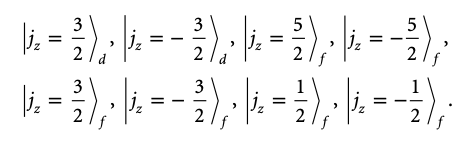

BasisSmB6 = Basis([ ...
    Spin(3/2,3/2,'parity',1); ...
    Spin(3/2,-3/2,'parity',1); ...
    Spin(5/2,5/2,'parity',-1); ...
    Spin(5/2,-5/2,'parity',-1); ...
    Spin(5/2,3/2,'parity',-1); ...
    Spin(5/2,-3/2,'parity',-1); ...
    Spin(5/2,1/2,'parity',-1); ...
    Spin(5/2,-1/2,'parity',-1) ...
    ]);
SmB6BasisFunction = BasisSmB6.BasisL

SmB6BasisFunction = |3/2,3/2⟩ 
|3/2,-3/2⟩ 
|5/2,5/2⟩ 
|5/2,-5/2⟩ 
|5/2,3/2⟩ 
|5/2,-3/2⟩ 
|5/2,1/2⟩ 
|5/2,-1/2⟩ 

Inv = SmB6BasisFunction.rotation(diag([-1 -1 -1]))

$$Inv = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & -1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & -1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & -1 \end{array}\right)$$

Tr=SmB6BasisFunction.Tr()

Tr =      0    -1     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0    -1     0     0     0
     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     1     0


C4z = rewrite(SmB6BasisFunction.rotation([0 0 1 sym(pi/2) 1]),'exp')

$$C4z = \left(\begin{array}{cccccccc} \sqrt{2}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right) & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & \sqrt{2}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sqrt{2}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & \sqrt{2}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right) & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & \sqrt{2}\,\left(-\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right) & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & \sqrt{2}\,\left(-\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & \sqrt{2}\,\left(\frac{1}{2}+\frac{1}{2}\,\mathrm{i}\right) & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & \sqrt{2}\,\left(\frac{1}{2}-\frac{1}{2}\,\mathrm{i}\right) \end{array}\right)$$

C2y = SmB6BasisFunction.rotation(diag([-1 1 -1]))

$$C2y = \left(\begin{array}{cccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ -1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 & -1 & 0 \end{array}\right)$$

## 6. Orbtital rotation

#### 6.1 TEST

TBGeffect = HR(4);
TBGeffect = TBGeffect <'POSCAR_TBGeffect';
hexagonalgroup = Oper.hexagonal(false);
hexagonalgroup = hexagonalgroup.attachRm(TBGeffect.Rm)

hexagonalgroup =   1 : 1
  2 : I
  3 : R(pi,[0 0 1])
  4 : R(pi,[0 1 0])
  5 : M([1 0 0])
  6 : R(pi,[-0.5 0.87 0])
  7 : M([0.87 0.5 0])
  8 : S(pi/3,[0 0 1])
  9 : R((2*pi)/3,[0 0 1])
 10 : S(pi/3,[0 0 1])
 11 : R((2*pi)/3,[0 0 1])
 12 : R(pi,[0.5 0.87 0])
 13 : M([0.87 -0.5 0])
 14 : R(pi,[0.87 -0.5 0])
 15 : M([0.5 0.87 0])
 16 : S((2*pi)/3,[0 0 1])
 17 : R(pi/3,[0 0 1])
 18 : S((2*pi)/3,[0 0 1])
 19 : R(pi/3,[0 0 1])
 20 : R(pi,[0.87 0.5 0])
 21 : M([-0.5 0.87 0])
 22 : R(pi,[1 0 0])
 23 : M([0 1 0])
 24 : M([0 0 1])
 25 : P P
 26 : I P
 27 : R(pi,[0 0 1]) P
 28 : R(pi,[0 1 0]) P
 29 : M([1 0 0]) P
 30 : R(pi,[-0.5 0.87 0]) P
 31 : M([0.87 0.5 0]) P
 32 : S(pi/3,[0 0 1]) P
 33 : R((2*pi)/3,[0 0 1]) P
 34 : S(pi/3,[0 0 1]) P
 35 : R((2*pi)/3,[0 0 1]) P
 36 : R(pi,[0.5 0.87 0]) P
 37 : M([0.87 -0.5 0]) P
 38 : R(pi,[0.87 -0.5 0]) P
 39 : M([0.5 0.87 0]) P
 40 : S((2*pi)/3,[0 0 1]) P
 41 : R(pi/3,[0 0 1]) P
 42 : S((2*pi)/3,[0 0 1]) P
 43 : R(pi/3,[0 0 1]) P
 44 : R(pi,[0.87 0.5 0]) 

BasisFunctionTBGeffect= BasisFunc(TBGeffect);

TestSymmetry = 17 ;
Opertmp = hexagonalgroup(TestSymmetry)

Opertmp =   Oper with properties:

               e: 0
               R: [3×3 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0
              Rf: [3×3 double]
              tf: [0 0 0]
               U: NaN

U·H(k)·U^-1 = H(R·k)
R = R(pi/3,[0 0 1])


BasisFunctionTBGeffect.rotation('Oper',Opertmp)

ans =      0     0     1     0
     0     0     0     1
     1     0     0     0
     0     1     0     0


## 5. Rotation Angle Convert Test

syms theta
theta = pi/6

theta = 0.5236

rotm = Oper.axang2rotm([0,0,1,theta])

rotm =     0.8660   -0.8660         0
    0.8660    0.8660         0
         0         0    1.2679


eul = Oper.Rotation2eul( rotm)

eul =          0         0    0.7854


rotm = Oper.axang2rotm([0,1,0,theta])

rotm =     0.8660         0    0.8660
         0    1.2679         0
   -0.8660         0    0.8660


eul = Oper.Rotation2eul( rotm)

eul =    -3.1416   -0.7854   -3.1416


rotm2eul( rotm,'ZYZ')

ans =    -3.1416   -0.7854   -3.1416


## 6. 

## A Note on Units in Our Programs


$$\hbar =1$$


## Conclusions

## References